cell_num = 4

cell_num = 4

log_area = log(data(cell_num,:,2));
div_threshold = 0.2;
max_gr = 0.05;

Plot of log area for a mother cells growth

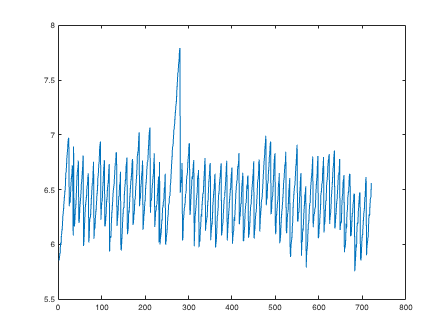

plot(log_area);

gr = diff(log_area);

Taking the derivative of the log area plot. Will set all values below the threshold of -0.4 to 0

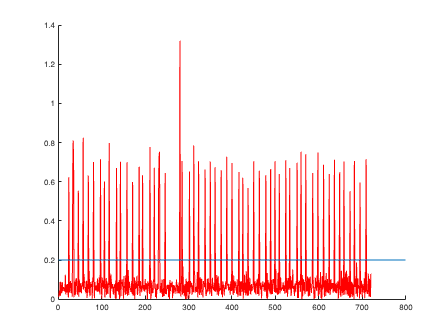

clf
hold on
plot(abs(gr),'Color','r')
line([0,800],[1,1]*div_threshold)
hold off

Setting all values below the threshold of -0.4 to 0

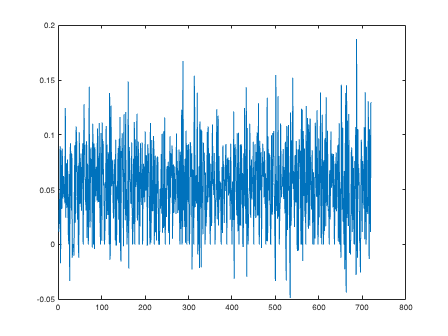

gr(abs(gr)>div_threshold)=0;
plot(gr)

Finding the cumulative sum of the above graph to find the lagtime graph

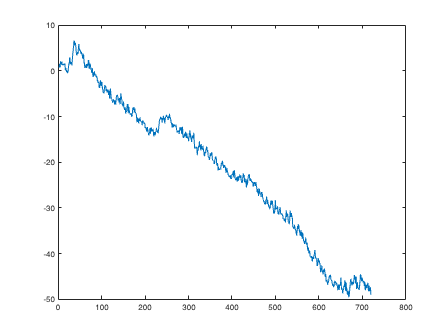

lagt = (1:720) - cumsum(gr)/max_gr;
clf
plot(lagt)

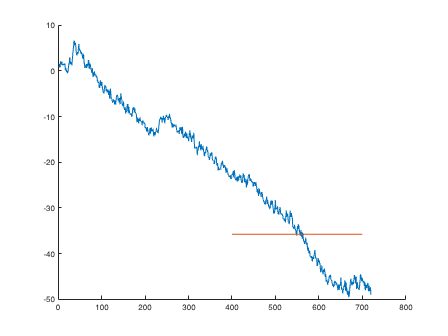

range_fit = 400:700;
lag_asym = polyfit(range_fit,lagt(1,range_fit),0);

lagt_in_range = lagt(1,range_fit);

clf
hold on
plot(lagt);
plot(range_fit,lag_asym*ones(1,length(range_fit)));
hold off

clf
cv = std(lagt_in_range-lag_asym)/mean(lagt_in_range-lag_asym)

cv = 1.0396e+15

The lagtime is the asymptote of the above graph, hence this cell has a lagtime of roughly 

Which is roughly 101 timepoints hence 202 minutes : 3h 22minutes at which point it reaches its exponential growth phase

cell_num =80;
range = 10:720;
log_area = log(data(cell_num,:,2));
[lagt,asym,csum,cv] = lagtime(0.05,log_area,range);
cv

cv = 8.2697e+14

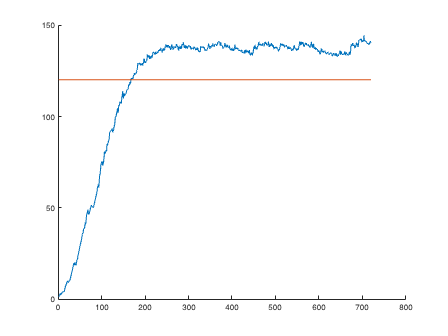

Unrecognized function or variable 'rfft'.

clf
hold on
plot(lagt)
plot(1:720,asym.*ones(1,720));

hold off

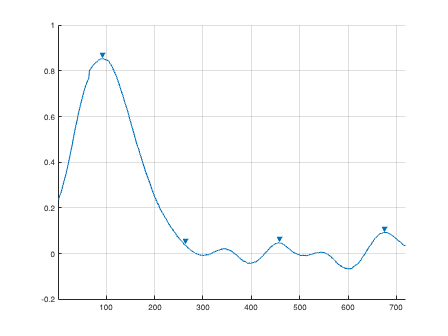

clf
smooth_lagt =  smoothdata(lagt,'gaussian');
hold on
%plot(smooth_lagt)
findpeaks(diff(smooth_lagt),"SortStr",'descend','MinPeakDistance',100)
[pks,locs] = findpeaks(diff(smooth_lagt),"SortStr",'descend','MinPeakDistance',100);
hold off

plot(csum)
CV = [];
ASYM = [];
YFP = [];
for c=1:178
    log_area = log(data(c,:,2));
    yfp = mean(data(c,range,36));
    [lagt,asym,csum,cv] = lagtime(0.05,log_area,range);
    CV = [CV, cv];
    ASYM = [ASYM,asym];
    YFP = [YFP, yfp];
end

histogram(YFP,150)
xlim([0,1000])

clf
log_CV = sign(CV).*log(abs(CV));
hold on
scatter(ASYM,log_CV,'filled','r')
scatter(ASYM(log_CV<0 & ASYM>20),log_CV(log_CV<0 & ASYM>20),'filled','g')
hold off
keep_asym_res = ASYM(log_CV<0 & ASYM>20 & YFP > 250);
mean_keep_asym_res = mean(keep_asym_res);
std_keep_asym_res = std(keep_asym_res);

keep_asym_sens = ASYM(log_CV<0 & ASYM>20 & YFP <= 250);
mean_keep_asym_sens = mean(keep_asym_sens);
std_keep_asym_sens = std(keep_asym_sens);

clf
hold on
histogram(keep_asym_sens,30,'FaceColor','red','FaceAlpha',0.4,'EdgeAlpha',0.2)
histogram(keep_asym_res,30,'FaceColor','yellow','FaceAlpha',0.4,'EdgeAlpha',0.2)
hold off
xlabel("lag time to exponential phase")
title(["distributions of ag time to exponential phase",...
    "sensitive(μ,σ): ("+num2str(mean_keep_asym_sens)+","+...
    num2str(std_keep_asym_sens)+")", ...
    "resistant(μ,σ): ("+num2str(mean_keep_asym_res)+","+...
    num2str(std_keep_asym_res)+")"])
legend(["sensitive","resistant"])